filepath= "images\starfish_5.jpg";
disp(filepath)

images\starfish_5.jpg


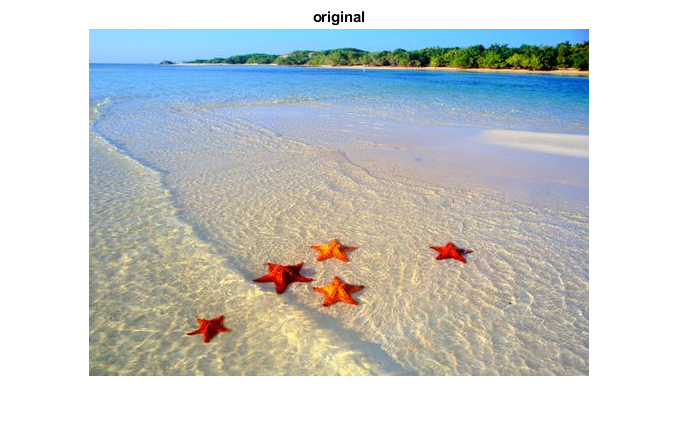

oIm = imread(filepath);
imshow(oIm);
title("original");

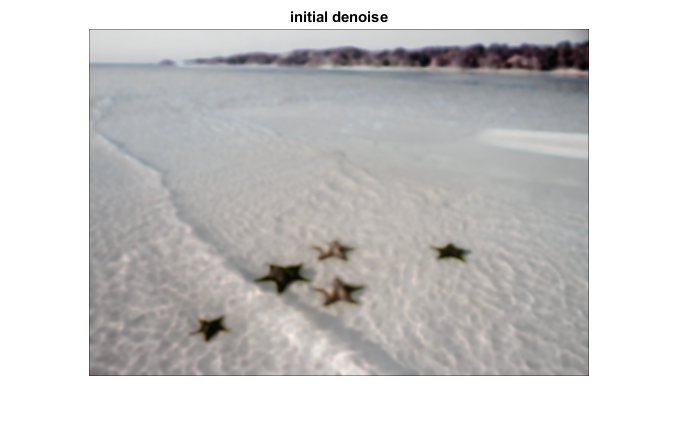



oIm = medfilt3(oIm, [5 5 5]);
oIm = imfilter(oIm, ones(3)/9, 'same');
imshow(oIm);
title("initial denoise");

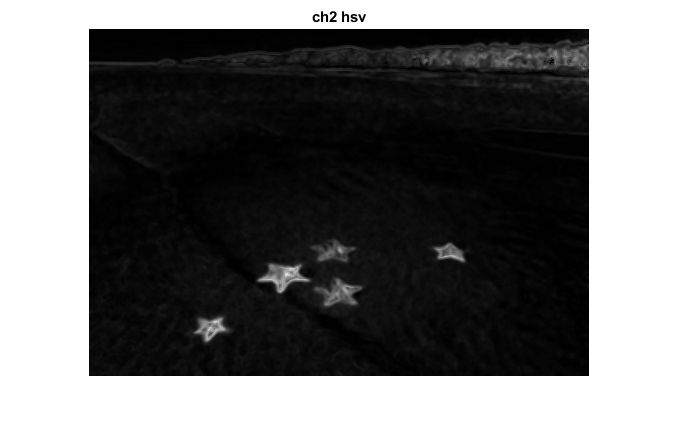



oIm = rgb2hsv(oIm);
oIm = oIm(:,:,2);
imshow(oIm);
title("ch2 hsv");



im = adapthisteq(oIm);
im = DenoiseIsolated(im);

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

noiseVal = 0.6530

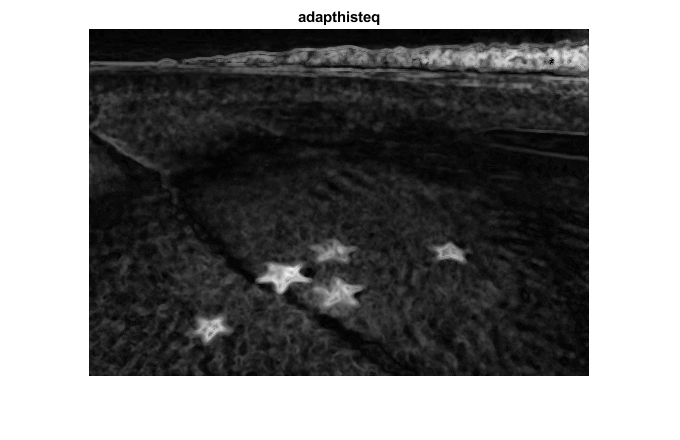

imshow(im);
title("adapthisteq")

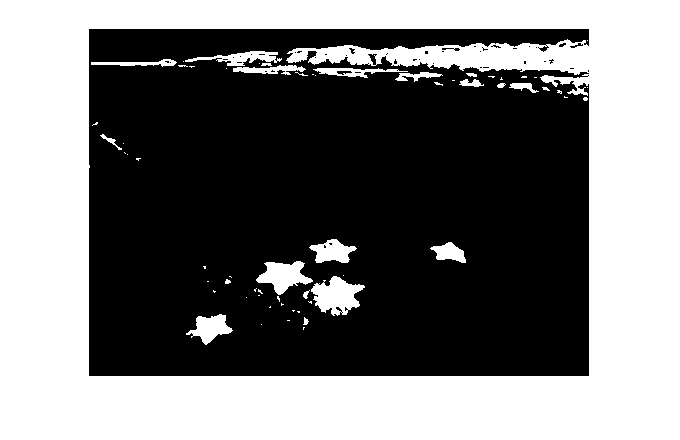

level = graythresh(im);
im = imbinarize(im, level);
imshow(im);

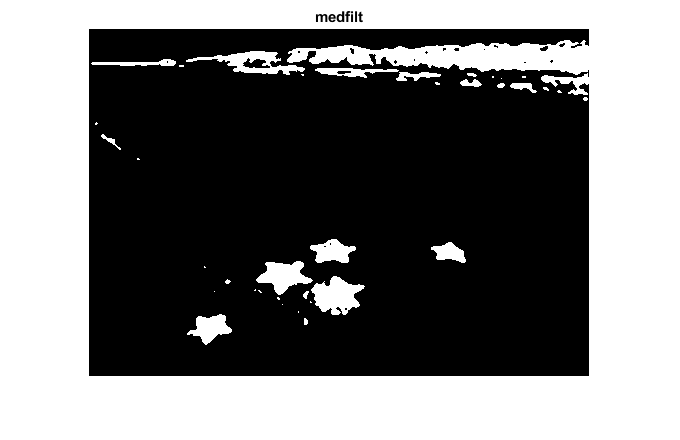



im = medfilt2(im, [3 3]);
imshow(im);
title("medfilt");

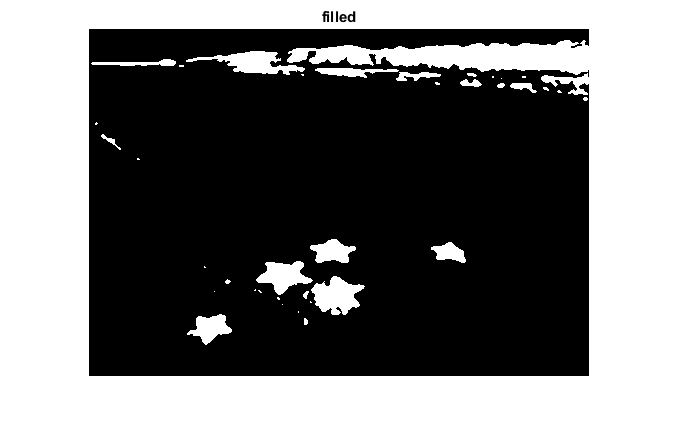



im = imfill(im, 'holes');
imshow(im);
title("filled");

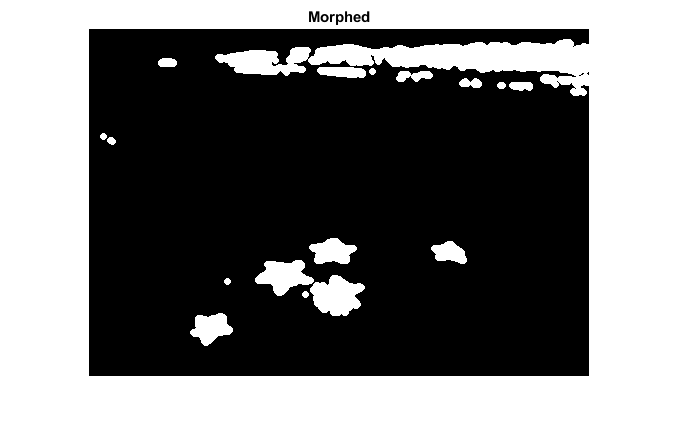



% Helps with the noiser images.
se = strel('disk', 2);
im = imerode(im, se);
% General morph ops.
se = strel('line', 3, 45);
im = imdilate(im, se);
se = strel('line', 3, 90);
im = imdilate(im, se);
se = strel('line', 3, 135);
im = imdilate(im, se);
se = strel('line', 3, 180);
im = imdilate(im, se);
imshow(im);
title("Morphed");



[cc, n] = bwlabel(im);
props = regionprops('table', im, 'all')

props = 17×30 table
    Area        Centroid                  BoundingBox                         SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage       ConvexArea    Circularity         Image            FilledImage       FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxFeretCoordinates    MinFeretDiameter

areaSTD = std(props.Area)

areaSTD = 2.1110e+03

areaMEAN = mean(props.Area)

areaMEAN = 904.1176

areaMeanPlusStd = areaMEAN + areaSTD;
areaMeanMinusStd = areaMEAN - areaSTD;
ccProps = regionprops(cc,'Area') ; % Get region info from region properties
for i = 1 : n
%     JroiX = imcrop(oIm, info(i).Area);
    % If area of blob outside of mean, remove it.
    if (ccProps(i).Area < areaMeanMinusStd || ccProps(i).Area > areaMeanPlusStd)
        removeMask = cc == i; % Get CC pixels by id.
        im(removeMask) = 0; % Set CC pixels to 0.
        disp("Removed mask " + i)
    end
end

Removed mask 5


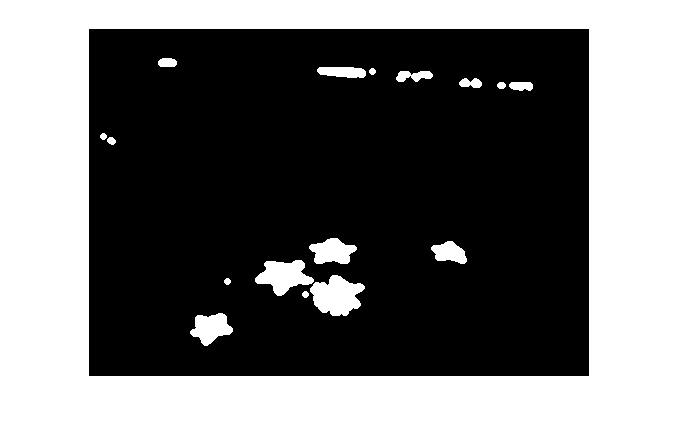

imshow(im);

function imP = DenoiseIsolated(im)
    scaler = 1;
    if (max(im(:)) <= 1)
        scaler = 255; % Scale grayscale values.
    end
    THRESHOLD = 50 / scaler;
    PIXEL_DIFF_THRESHOLD = 20 / scaler;
    MAX_PASSES = 10;
    filtered = medfilt2(im, [5 5]);
    noiseVal = THRESHOLD + 1;
    nPasses = 0;
    
    while (noiseVal > THRESHOLD && nPasses < MAX_PASSES)
        noise = im - filtered;
        noiseMask = noise > PIXEL_DIFF_THRESHOLD;
        imP = im;
        imP(noiseMask) = filtered(noiseMask);
        noisyPixels = sum(noiseMask(:));
        nPx = numel(im);
        noiseVal = (100/nPx) * noisyPixels
        nPasses = nPasses + 1;
    end
end